# ** ECON 310: Dynamic Macroeconomics**

### **Spring 2025**

### **Fulbright University Vietnam**

%{

    run_slcm.mlx
    ------------
    This code solves the stochastic life cycle model using backward induction.

%}

## Model: Stochastic Life Cycle Model.

The representative consumer is born in period $0$ and lives up to $T-1$. Her working life is from period $0$ to $t_r-1$, where she receives exogenous labor income, $y_t$. From period $t_r$ onward, she is retired and receives a pension equal to some fraction, $0<\kappa<1$, of her labor income in the last period of her working life. She maximizes lifetime utility by choosing consumption and savings, subject to a dynamic budget con    straint in each period. Her optimization problem is:


$$\underset{\{c_t\}_{t=1}^{T-1},\{a_{t+1}\}_{t=0}^{T-1}}{\text{max }} \mathbb{E}_0\left(U\right) =  \mathbb{E}_0\left[\sum_{t=1}^{T-1} \beta^{t} \frac{c_t^{1-\sigma}}{1-\sigma}\right] \text{ ,}$$


 
$$\text{s.t. } a_{t+1} = (1+r)(a_t+y_t-c_t)  \ , $$



$$y_t = \begin{cases}
		\text{exp}(\rho \ \text{log} \ y_{t-1} + \epsilon_t) & \ \text{if} \ t<t_r \\
		\kappa y_{t_r-1} & \ \text{if} \ t\geq t_r
	\end{cases} \ , $$



$$a_0 \ \text{given} \ ,$$



$$a_T = 0 \ , \\ 
c_t > 0 \ ,  $$


for all $t = 0, 1, ..., T-1$ and where $|\rho|<1$ and $\epsilon_t\sim\mathcal{N}(0,\sigma^2)$. The consumer has an initial wealth endowment, $a_0\geq0$, and the real interest rate, $r$, is fixed. You will gradually extend, solve, and simulate this model. When simulating the model, initialize the state variables, including age: for the endogenous state variables, assume equal probabilities for each state; for any exogenous Markov process, draw from the stationary distribution. In each simulation, you must have a panel of 1000 consumers over 30 periods. 

## Recursive Formulation.

The recursive formulation  is


$$V_t(a_t,t,y_t) = \underset{c_t, a_{t+1}}{\text{max}}\frac{c_t^{1-\sigma}}{1-\sigma} + \beta \mathbb{E}_0\left[V_{t+1}(a_{t+1},t+1,y_{t+1})\right] \ ,$$


 
$$\text{s.t. } a_{t+1} = (1+r)(a_t+y_t-c_t)  \ , $$



$$y_t = \begin{cases}
		\text{exp}(\rho \ \text{log} \ y_{t-1} + \epsilon_t) & \ \text{if} \ t<t_r \\
		\kappa y_{t_r-1} & \ \text{if} \ t\geq t_r
	\end{cases} \ , $$



$$a_0 \ \text{given} \ ,$$



$$a_T = 0 \ , \\ 
c_t > 0 \ ,  $$


The state space consists only of $a_t$ while the choice space consists of $c_t$ and $a_{t+1}$. Substituting the budget constraint into the utility function gives


$$V_t(a_t,t,y_t) = \underset{a_{t+1}}{\text{max}}\frac{\left[a_t+y_t-\frac{a_{t+1}}{1+r}\right]^{1-\sigma}}{1-\sigma} + \beta \left[V_{t+1}(a_{t+1},t+1,y_{t+1})\right] \ ,$$



$$y_t = \begin{cases}
		\text{exp}(\rho \ \text{log} \ y_{t-1} + \epsilon_t) & \ \text{if} \ t<t_r \\
		\kappa y_{t_r-1} & \ \text{if} \ t\geq t_r
	\end{cases} \ , $$



$$a_0 \ \text{given} \ ,$$



$$a_T = 0 \ , \\ 
c_t > 0 \ ,  $$


which reduces the choice space to $a_{t+1}$.

## Set up directories and paths.

clc
clear
close all

id = getenv('USERNAME'); % Gets your username.

main = strcat('/Users/apple/Downloads/ps2'); % Project Folder.
cd (strcat(main)) % Set project folder as current working directory.

addpath(genpath(main)) % Add all subfolders in current working directory to path. Note: Make sure file names are unique.

fprintf('The directory is %s \n\n',main)

The directory is /Users/apple/Downloads/ps2 



## Set the parameters and generate the state space.

Calls: model.m.

The grid for assets is set exogenously.

par = model.setup; % Set parameters.
par = model.gen_grids(par); % Generate the state space.

## Solve the model using Backward Induction.

Calls: solve.m and model.m.

We will solve the model using backward induction. In the last period of life, it is optimal to consume everything


$$c_T = a_T + y_T \ .$$


t = cputime;
sol = solve.lc(par); % Solve the model using Backward Induction.

------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------



fprintf('\nModel solved in %0.4f seconds.\n', cputime-t)


Model solved in 0.9700 seconds.


## Simulate the model and plot the policy functions.

Calls: simulate.m and my_graph.m.

Simulate a population with heterogeneous age.

sim = simulate.lc(par,sol); % Simulate the model.

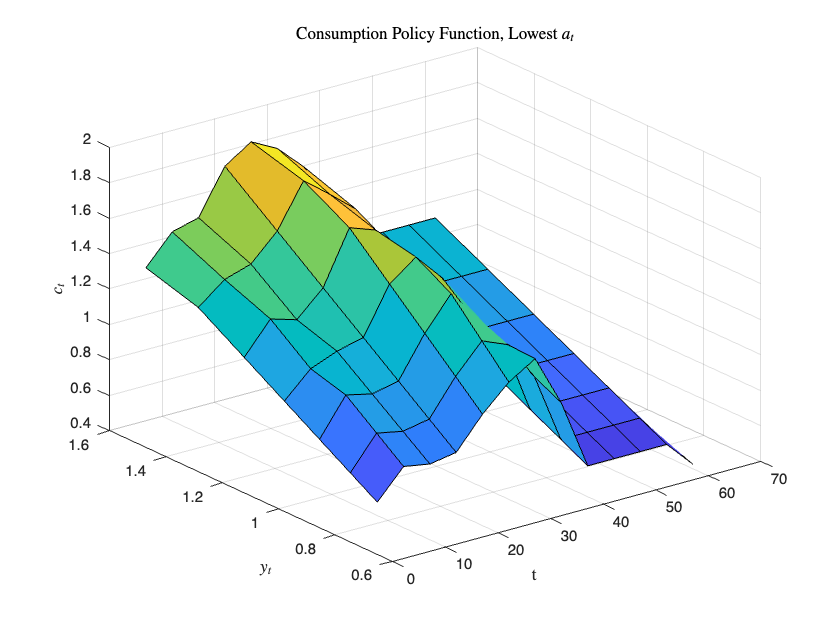

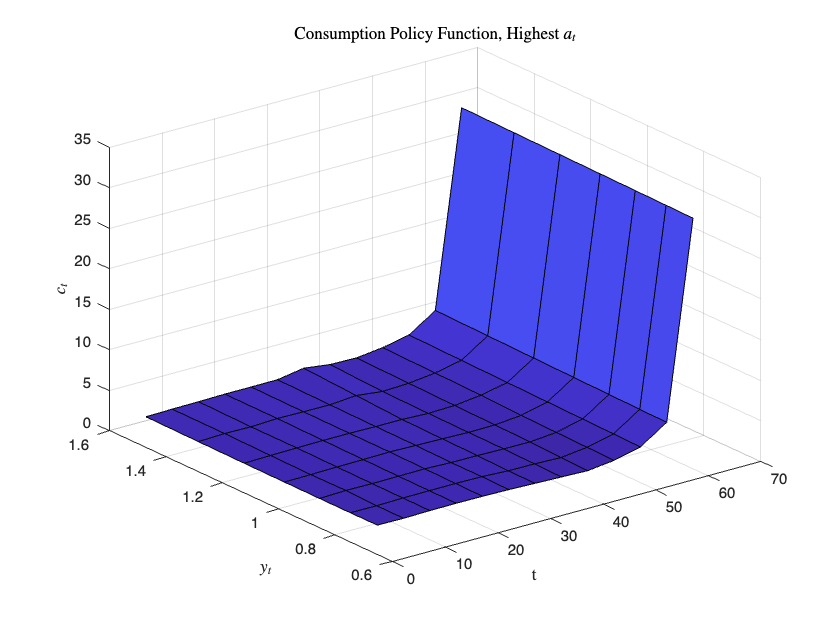

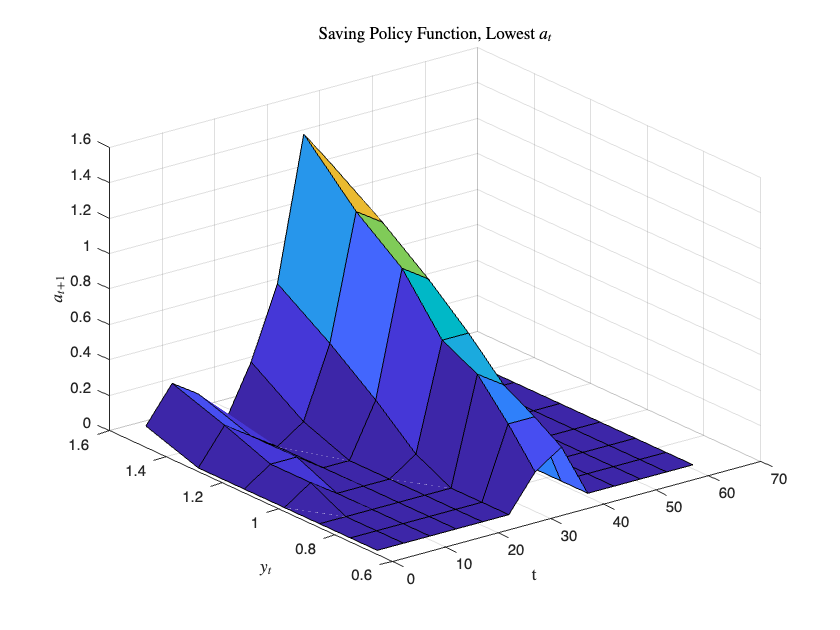

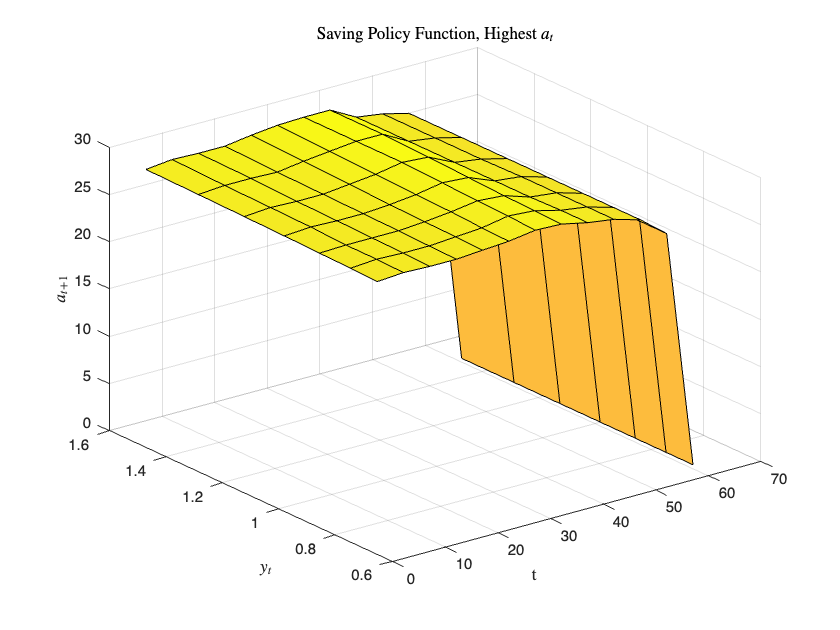

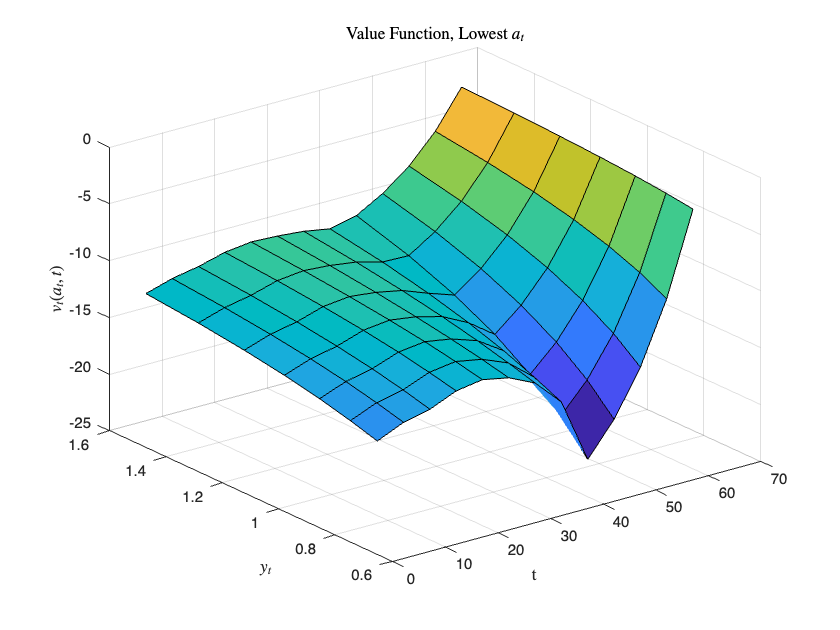

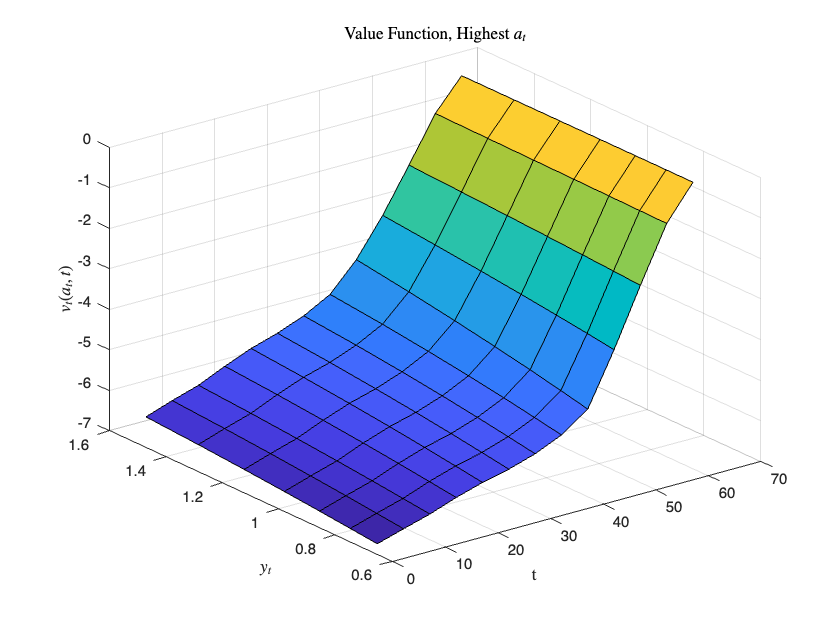

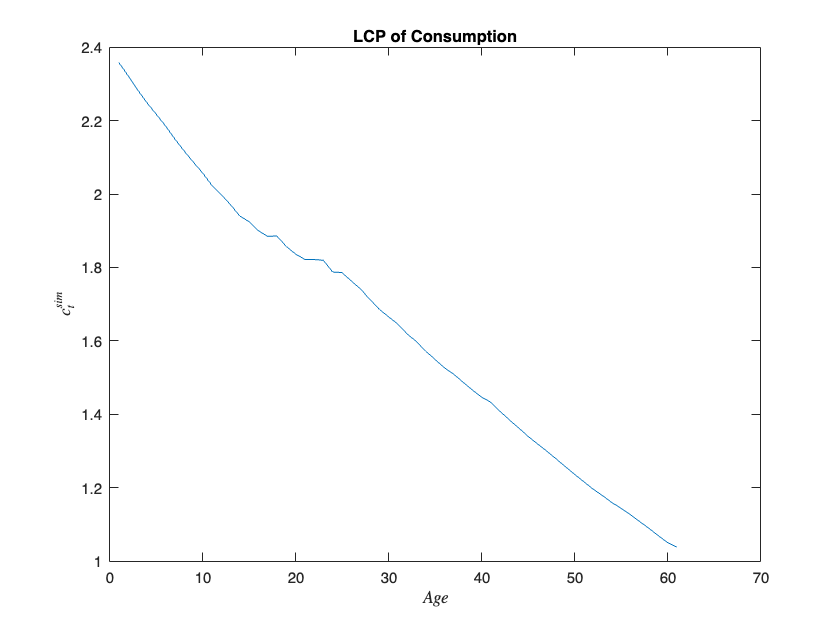

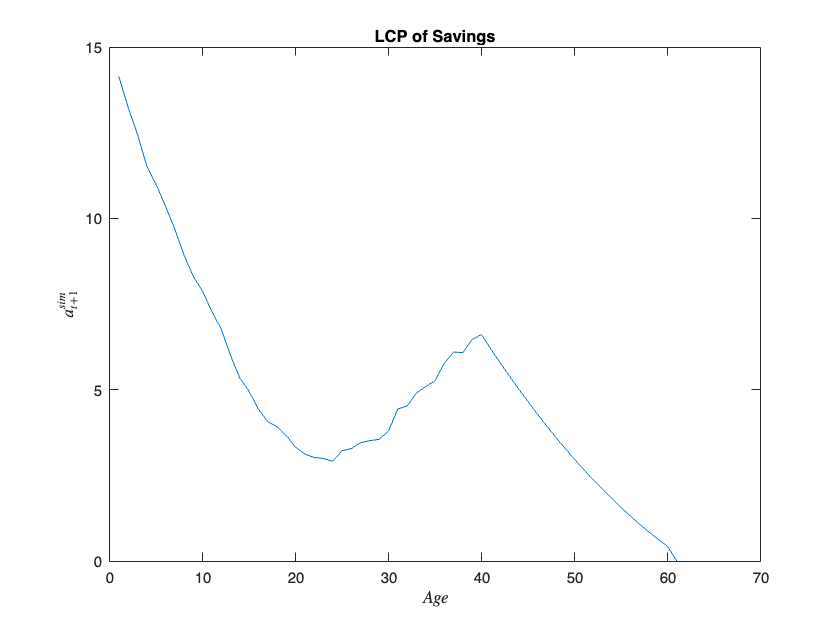

my_graph.plot_policy(par,sol,sim) % Plot the model functions and time series.

% γ = 2.00, β ∈ {0.90, 0.92, 0.94, 0.96}
beta_list = [0.90, 0.92, 0.94, 0.96];
gamma_fixed = 2.00;

% Initialize storage
par0 = model.setup();
T = par0.T;
avg_c_all = nan(length(beta_list), T);
avg_a_all = nan(length(beta_list), T);

% Loop over beta values
for b = 1:length(beta_list)
    % Set up model
    par = model.setup();
    par.sigma = gamma_fixed;
    par.beta = beta_list(b);
    par = model.gen_grids(par);
    
    % Solve and simulate
    sol = solve.lc(par);
    sim = simulate.lc(par, sol);
    
    % Compute lifecycle profiles
    lcp_c = nan(T,1);
    lcp_a = nan(T,1);
    for i = 1:T
        lcp_c(i) = mean(sim.csim(sim.tsim == i), "omitnan");
        lcp_a(i) = mean(sim.asim(sim.tsim == i), "omitnan");
    end
    avg_c_all(b, :) = lcp_c;
    avg_a_all(b, :) = lcp_a;
end

------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------
------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------
------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------
------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------


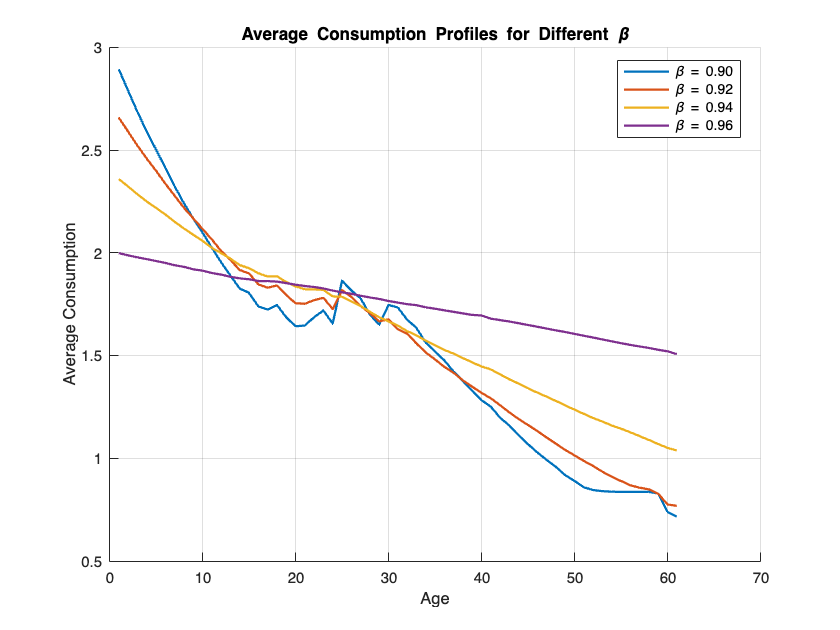


% Plot: Average Consumption Profiles
figure;
hold on;
colors = lines(length(beta_list));
for b = 1:length(beta_list)
    plot(1:T, avg_c_all(b, :), 'LineWidth', 1.5, 'Color', colors(b,:), ...
        'DisplayName', sprintf('\\beta = %.2f', beta_list(b)));
end
hold off;
xlabel('Age');
ylabel('Average Consumption');
title('Average Consumption Profiles for Different \beta');
legend('Location', 'best');
grid on;

% === Descriptive Statistics Table for Consumption ===
means_c = mean(avg_c_all, 2, 'omitnan');
stds_c  = std(avg_c_all, 0, 2, 'omitnan');
mins_c  = min(avg_c_all, [], 2);
maxs_c  = max(avg_c_all, [], 2);

desc_table_consumption = table(beta_list', means_c, stds_c, mins_c, maxs_c, ...
    'VariableNames', {'Beta', 'Mean', 'Std', 'Min', 'Max'});
disp("Descriptive Table – Consumption:");

Descriptive Table – Consumption:


disp(desc_table_consumption);

    Beta     Mean       Std        Min       Max  
    ____    ______    _______    _______    ______

     0.9    1.5507    0.56188    0.71608    2.8934
    0.92    1.5719     0.5104    0.76829    2.6579
    0.94    1.6389    0.37303     1.0378    2.3586
    0.96    1.7548    0.13989     1.5069    1.9982



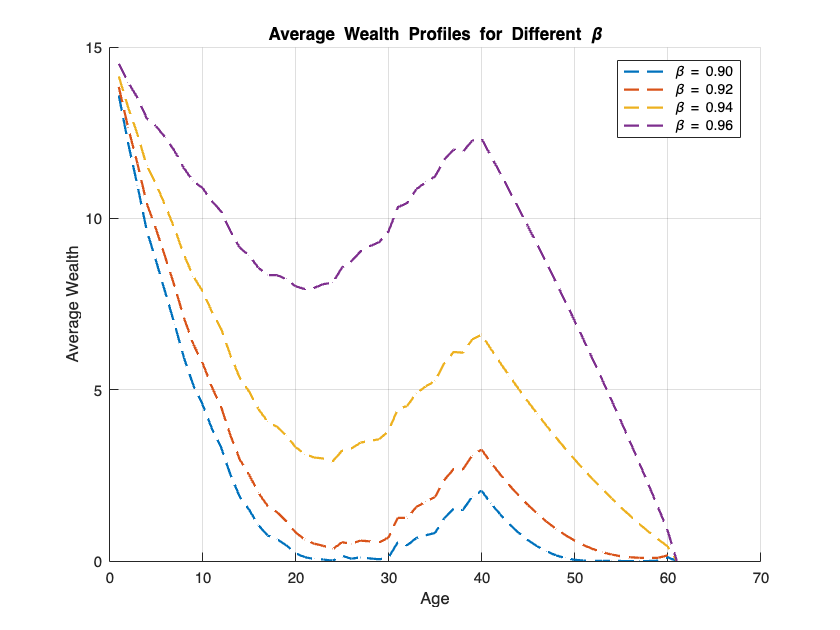



% Plot: Average Asset (Wealth) Profiles
figure;
hold on;
for b = 1:length(beta_list)
    plot(1:T, avg_a_all(b, :), '--', 'LineWidth', 1.5, 'Color', colors(b,:), ...
        'DisplayName', sprintf('\\beta = %.2f', beta_list(b)));
end
hold off;
xlabel('Age');
ylabel('Average Wealth');
title('Average Wealth Profiles for Different \beta');
legend('Location', 'best');
grid on;

% === Descriptive Statistics Table for Wealth ===
means_w = mean(avg_a_all, 2, 'omitnan');
stds_w  = std(avg_a_all, 0, 2, 'omitnan');
mins_w  = min(avg_a_all, [], 2);
maxs_w  = max(avg_a_all, [], 2);

desc_table_wealth = table(beta_list', means_w, stds_w, mins_w, maxs_w, ...
    'VariableNames', {'Beta', 'Mean', 'Std', 'Min', 'Max'});
disp("Descriptive Table – Wealth:");

Descriptive Table – Wealth:


disp(desc_table_wealth);

    Beta     Mean      Std      Min     Max  
    ____    ______    ______    ___    ______

     0.9    1.9793    3.2686     0     13.598
    0.92    2.7082    3.3696     0     13.841
    0.94    5.0091    3.1461     0     14.149
    0.96    8.9868     3.239     0      14.52



% β = 0.96, γ ∈ {2.00, 3.00, 4.00, 5.00}
beta_fixed = 0.96;
gamma_list = [2.00, 3.00, 4.00, 5.00];

% Initialize storage
par0 = model.setup();
T = par0.T;
avg_c_all = nan(length(gamma_list), T);
avg_a_all = nan(length(gamma_list), T);

% Loop over beta values
for b = 1:length(gamma_list)
    % Set up model
    par = model.setup();
    par.sigma = gamma_list(b);
    par.beta = beta_fixed;
    par = model.gen_grids(par);
    
    % Solve and simulate
    sol = solve.lc(par);
    sim = simulate.lc(par, sol);
    
    % Compute lifecycle profiles
    lcp_c = nan(T,1);
    lcp_a = nan(T,1);
    for i = 1:T
        lcp_c(i) = mean(sim.csim(sim.tsim == i), "omitnan");
        lcp_a(i) = mean(sim.asim(sim.tsim == i), "omitnan");
    end
    avg_c_all(b, :) = lcp_c;
    avg_a_all(b, :) = lcp_a;
end

------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------
------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------
------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------
------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------


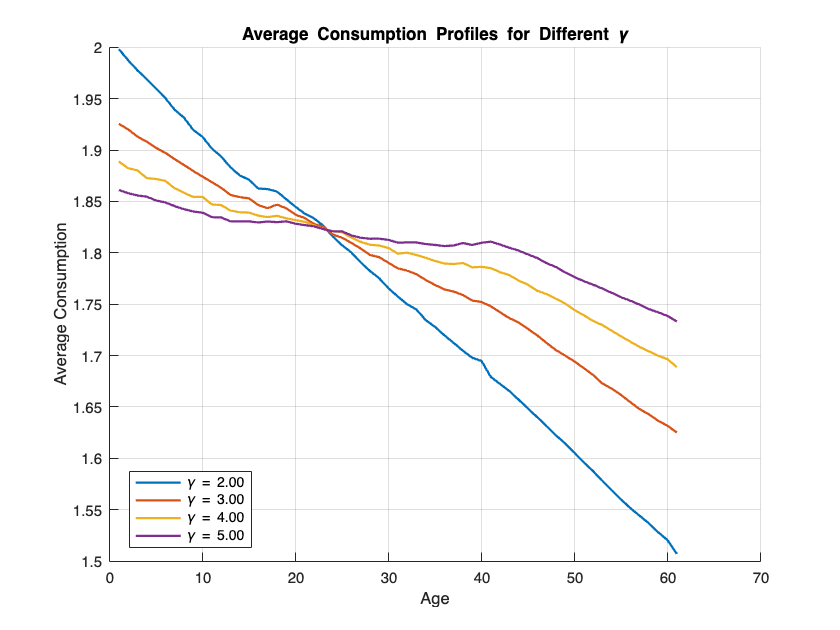


% Plot: Average Consumption Profiles
figure;
hold on;
colors = lines(length(gamma_list));
for b = 1:length(gamma_list)
    plot(1:T, avg_c_all(b, :), 'LineWidth', 1.5, 'Color', colors(b,:), ...
        'DisplayName', sprintf('\\gamma = %.2f', gamma_list(b)));
end
hold off;
xlabel('Age');
ylabel('Average Consumption');
title('Average Consumption Profiles for Different \gamma');
legend('Location', 'best');
grid on;

% Descriptive Statistics Table for Consumption 
means_c = mean(avg_c_all, 2, 'omitnan');
stds_c  = std(avg_c_all, 0, 2, 'omitnan');
mins_c  = min(avg_c_all, [], 2);
maxs_c  = max(avg_c_all, [], 2);

desc_table_consumption = table(gamma_list', means_c, stds_c, mins_c, maxs_c, ...
    'VariableNames', {'Gamma', 'Mean', 'Std', 'Min', 'Max'});
disp("Descriptive Table – Consumption:");

Descriptive Table – Consumption:


disp(desc_table_consumption);

    Gamma     Mean       Std        Min       Max  
    _____    ______    ________    ______    ______

      2      1.7548     0.13989    1.5069    1.9982
      3      1.7825    0.084076     1.625    1.9255
      4      1.7981     0.05257    1.6888    1.8888
      5      1.8085    0.032165    1.7331     1.861



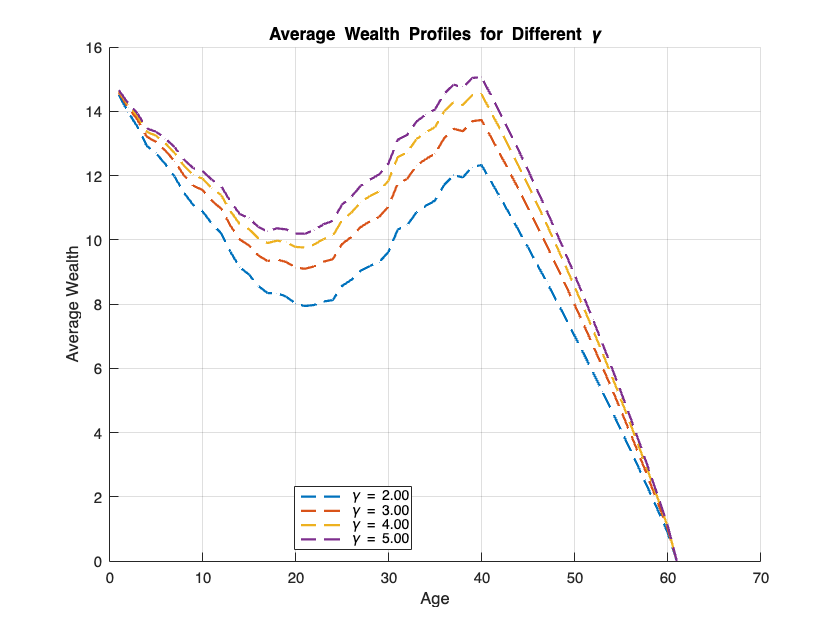


% Plot: Average Asset (Wealth) Profiles
figure;
hold on;
for b = 1:length(gamma_list)
    plot(1:T, avg_a_all(b, :), '--', 'LineWidth', 1.5, 'Color', colors(b,:), ...
        'DisplayName', sprintf('\\gamma = %.2f', gamma_list(b)));
end
hold off;
xlabel('Age');
ylabel('Average Wealth');
title('Average Wealth Profiles for Different \gamma');
legend('Location', 'best');
grid on;

% === Descriptive Statistics Table for Wealth ===
means_w = mean(avg_a_all, 2, 'omitnan');
stds_w  = std(avg_a_all, 0, 2, 'omitnan');
mins_w  = min(avg_a_all, [], 2);
maxs_w  = max(avg_a_all, [], 2);

desc_table_wealth = table(gamma_list', means_w, stds_w, mins_w, maxs_w, ...
    'VariableNames', {'Gamma', 'Mean', 'Std', 'Min', 'Max'});
disp("Descriptive Table – Wealth:");

Descriptive Table – Wealth:


disp(desc_table_wealth);

    Gamma     Mean      Std      Min     Max  
    _____    ______    ______    ___    ______

      2      8.9868     3.239     0      14.52
      3      9.9364    3.3951     0     14.595
      4      10.475    3.5044     0     14.633
      5       10.83    3.5845     0     15.068



% Parameters
gamma_list = [2.00, 3.00, 4.00, 5.00];
beta_list = [0.90, 0.92, 0.94, 0.96];

% Initialize results matrix
avg_wealth_matrix = nan(length(beta_list), length(gamma_list));

% Loop over combinations
for i = 1:length(beta_list)
    for j = 1:length(gamma_list)
        % Set up model
        par = model.setup();
        par.beta = beta_list(i);
        par.sigma = gamma_list(j);
        par = model.gen_grids(par);

        % Solve and simulate
        sol = solve.lc(par);
        sim = simulate.lc(par, sol);

        % Compute average wealth over all periods and individuals
        avg_wealth = mean(sim.asim(:), "omitnan");
        avg_wealth_matrix(i, j) = avg_wealth;
    end
end

------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------
------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------
------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------
------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------
------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.

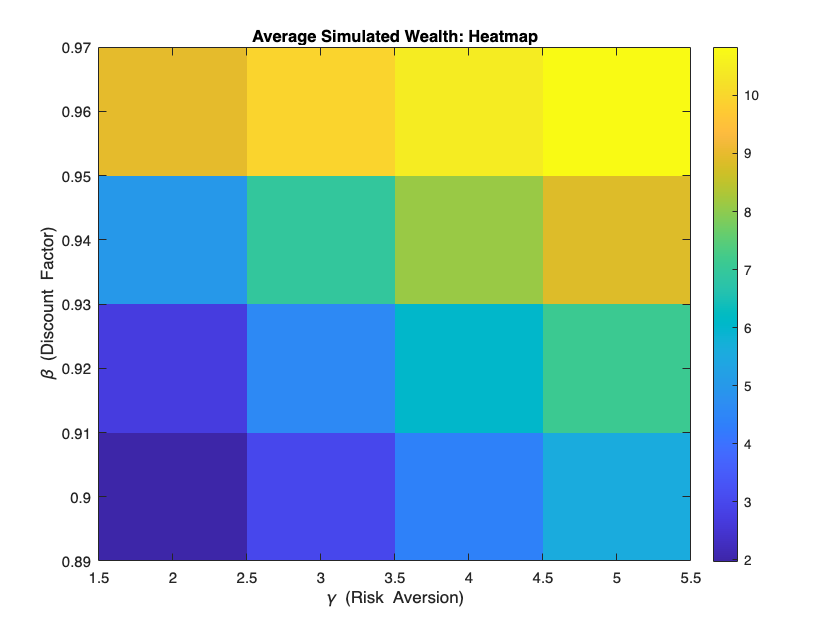


% Plot the heatmap
figure;
imagesc(gamma_list, beta_list, avg_wealth_matrix);
colorbar; 
xlabel('\gamma (Risk Aversion)');
ylabel('\beta (Discount Factor)');
title('Average Simulated Wealth: Heatmap');
set(gca, 'YDir', 'normal');